clc
clear
close all

#### **1. 基础坐标变换矩阵**

Rx = rotx(30,'deg')

Rx =     1.0000         0         0
         0    0.8660   -0.5000
         0    0.5000    0.8660


Ry = roty(45,'deg')

Ry =     0.7071         0    0.7071
         0    1.0000         0
   -0.7071         0    0.7071


Rz = rotz(60,'deg')

Rz =     0.5000   -0.8660         0
    0.8660    0.5000         0
         0         0    1.0000


#### 2. 坐标变换矩阵-中间轴-欧拉角

% 复合旋转：Z-Y—X
Rb = rotz(pi/3) * roty(pi/4) * rotx(pi/6)

Rb =     0.3536   -0.5732    0.7392
    0.6124    0.7392    0.2803
   -0.7071    0.3536    0.6124


#### 3. 坐标变化矩阵-固定轴-欧拉角

% 滚动-俯仰-偏航（Roll-Pitch-Yaw），默认绕固定轴Z-Y-X旋转
Ro = rotx(pi/6) * roty(pi/4) * rotz(pi/3)

Ro =     0.3536   -0.6124    0.7071
    0.9268    0.1268   -0.3536
    0.1268    0.7803    0.6124


#### 4. 齐次坐标变换矩阵（Homogeneous Transformation Matrix）

T1 = transl(3, 2, 1)

T1 =      1     0     0     3
     0     1     0     2
     0     0     1     1
     0     0     0     1


T2 = trotx(pi/6) 

T2 =     1.0000         0         0         0
         0    0.8660   -0.5000         0
         0    0.5000    0.8660         0
         0         0         0    1.0000


T3 = troty(pi/6) 

T3 =     0.8660         0    0.5000         0
         0    1.0000         0         0
   -0.5000         0    0.8660         0
         0         0         0    1.0000


T4 = trotx(pi/6) 

T4 =     1.0000         0         0         0
         0    0.8660   -0.5000         0
         0    0.5000    0.8660         0
         0         0         0    1.0000


### 5. 正运动学：D-H法则构建连杆

clc
clear
close all

% d        theta               a           alpha           offset 
d1 = 1.2;  theta1 = 0.0;      a1 = 0.2;   alpha1 = pi/2;   ofs1 = 0;
d2 = 0.0;  theta2 = 0.0;      a2 = 0.6;   alpha2 = pi/2;   ofs2 = 0;

% 生成连杆1，2
L1 = Link('d', d1, 'a', a1, 'alpha', alpha1, 'offset', ofs1, 'revolute')

 
L1 = 
Revolute(std): theta=q, d=1.2, a=0.2, alpha=1.5708, offset=0


L2 = Link('prismatic', 'theta', theta2, 'a', a2, 'alpha', alpha2, 'offset', ofs2, 'qlim',[0.5,2])

 
L2 = 
Prismatic(std): theta=0, d=q, a=0.6, alpha=1.5708, offset=0



% 生成机器人
bot = SerialLink([L1 L2], 'name', 'my robot')

 
bot = 
 
my robot:: 2 axis, RP, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        1.2|        0.2|     1.5708|          0|
|  2|          0|         q2|        0.6|     1.5708|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


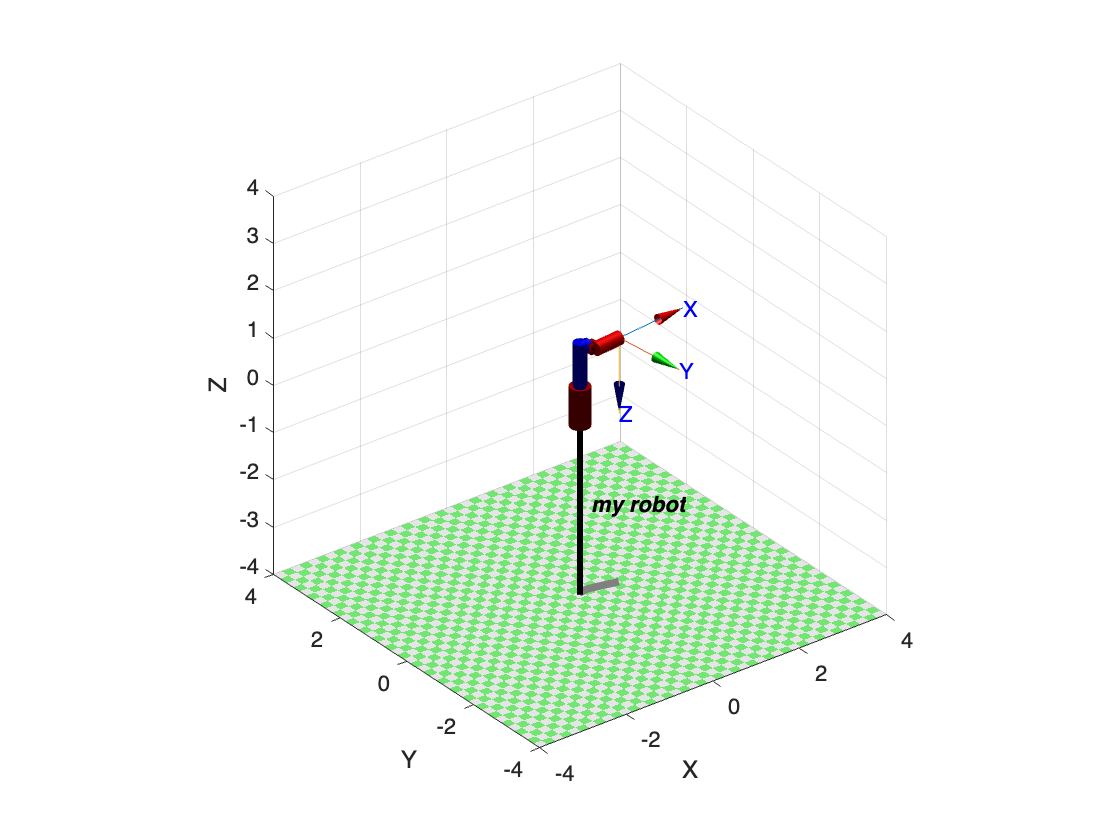


% 用Fkine求正运动学，即获得坐标变换矩阵
qz = [0.1, 0.2];
qs = [pi/3, 1.5];
bot.plot(qz);       %显示qz位姿的机器人

T = bot.fkine(qs)   %显示末端坐标系的T阵

 

T = 
    0.5000    0.8660         0     1.699
    0.8660   -0.5000         0  -0.05718
         0         0        -1       1.2
         0         0         0         1



% 根据D-H法则，手动计算的坐标变换矩阵
theta1 = qs(1); d2 = qs(2);

T01A = transl(0,0,d1)*trotz(theta1);
T01B = transl(a1,0,0)*trotx(alpha1);
T01 = T01A * T01B

T01 =     0.5000         0    0.8660    0.1000
    0.8660         0   -0.5000    0.1732
         0    1.0000         0    1.2000
         0         0         0    1.0000



T12A = transl(0,0,d2)*trotz(theta2);
T12B = transl(a2,0,0)*trotx(alpha2);
T12 = T12A*T12B

T12 =     1.0000         0         0    0.6000
         0         0   -1.0000         0
         0    1.0000         0    1.5000
         0         0         0    1.0000



T02 = T01*T12

T02 =     0.5000    0.8660         0    1.6990
    0.8660   -0.5000         0   -0.0572
         0         0   -1.0000    1.2000
         0         0         0    1.0000


% T和T02是一致的。


### 6. 逆运动学求解

mdl_puma560                 
% create the model
% forward kinematics of a known set of joing angles
p560

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


T = p560.fkine(qn)

 

T = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1



% inverse kinematics - right handed, elbow up
qn_r1 = p560.ikine6s(T,'ru')

qn_r1 =    -0.0000    0.7854    3.1416   -0.0000    0.7854    0.0000



% 也可以这样(注意这里用的是右侧下肘的位形)：
qn_r2 = ikine6s(p560,T,'rd')

qn_r2 =    -0.0000   -0.8335    0.0940   -3.1416    0.8312    3.1416



% default IK
qn_r3 = p560.ikine(T)

qn_r3 =    -0.0000   -0.8335    0.0940    0.0000   -0.8312   -0.0000


mask = [1 1 1 1 1 1];
qn_r3 = p560.ikine(T,'mask',mask)

qn_r3 =    -0.0000   -0.8335    0.0940    0.0000   -0.8312   -0.0000


### **7. 速度运动学**

qz = [0 0 0 0 0 0];         % zero angles, L shaped pose
qr = [0 pi/2 -pi/2 0 0 0];  % ready pose, arm up
qs = [0 0 -pi/2 0 0 0];     % initial pose
qn = [0 pi/4 pi 0 pi/4  0]; % 

% This Jacobian is often referred to as the geometric Jacobian.
Jz = p560.jacobe(qz)

Jz =     0.1500   -0.4318   -0.4318         0         0         0
    0.4521    0.0000    0.0000         0         0         0
         0    0.4521    0.0203         0         0         0
         0         0         0         0         0         0
         0   -1.0000   -1.0000         0   -1.0000         0
    1.0000    0.0000    0.0000    1.0000    0.0000    1.0000



% This Jacobian is often referred to as the geometric Jacobian.
Jn = p560.jacobe(qn)

Jn =    -0.0000   -0.5963   -0.2910         0         0         0
    0.5963    0.0000    0.0000         0         0         0
    0.1500    0.0144    0.3197         0         0         0
   -1.0000         0         0    0.7071         0         0
   -0.0000   -1.0000   -1.0000   -0.0000   -1.0000         0
   -0.0000    0.0000    0.0000    0.7071    0.0000    1.0000



% 'trans'   Return translational submatrix of Jacobian
Jn_t = p560.jacobe(qn,'trans' )

Jn_t =    -0.0000   -0.5963   -0.2910         0         0         0
    0.5963    0.0000    0.0000         0         0         0
    0.1500    0.0144    0.3197         0         0         0



% 'rot'     Return rotational submatrix of Jacobian 
Jn_r = p560.jacobe(qn,'rot' )

Jn_r =    -1.0000         0         0    0.7071         0         0
   -0.0000   -1.0000   -1.0000   -0.0000   -1.0000         0
   -0.0000    0.0000    0.0000    0.7071    0.0000    1.0000


% 关节空间轨迹规划（P2P-straight line）

#### 8. 轨迹规划（P2P-straight line）

clc
clear
close all

% +++++++++++++++++++++++++++++++++++++++++++++++++
% Robot by DH parameters
%           theta d    a    alpha       offset      
L(1) = Link([0    0    0     -pi/2      0]);
L(2) = Link([0    0    1     0          0]);
L(3) = Link([0    0    1     0          0]);
robot = SerialLink(L, 'name', '3-Link Bot')

 
robot = 
 
3-Link Bot:: 3 axis, RRR, stdDH, slowRNE                         
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|    -1.5708|          0|
|  2|         q2|          0|          1|          0|          0|
|  3|         q3|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


m = [1,1,1,0,0,0];

% +++++++++++++++++++++++++++++++++++++++++++++++++
% 采样时间为T，采样间隔为0.01s
T = 2;
dT = 0.05;
t = 0: dT: T;  

% 笛卡尔空间中的起点和终点
Ts = transl(1.2, -0.2, -0.5) ;  % 如果有姿态再用上trotex,y,z等函数
Te = transl(-0.8, 0.8,  0.7) ;

% 关节空间的起点和终点
% 可以直接从关节空间中指定，此处为了显示动画的设计更好理解，从笛卡尔空间变换过来
qs0 = [0  0  0]; 
qs = robot.ikine(Ts,'q0', qs0, 'mask', m);

qe0 = [0  0  0]; 
qe = robot.ikine(Te,'q0', qe0, 'mask', m);

% 关节空间轨迹规划
% 默认采用（关节空间）五阶多项式，速度和加速度为零边界条件 
[q, qd, qdd] = jtraj(qs, qe, t); 

% 笛卡尔空间轨迹规划
Nc =  T/dT+1;
Tc = ctraj(Ts, Te, Nc);
